# **HW14 [ALL CORRECT]**

## Q1 [CORRECT]

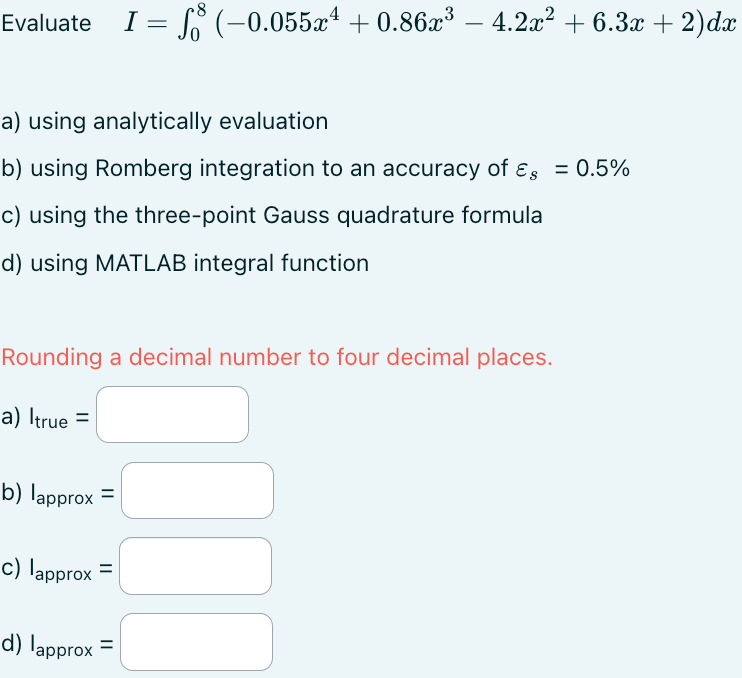

### a & d

f = @(x) -0.055.*x.^4 + 0.86.*x.^3 - 4.2.*x.^2 + 6.3.*x + 2;
a = 0; b = 8;
Iint = integral(f, a, b)

Iint = 20.9920

### b

Irb = romberg(f, a, b, 0.5)

Irb = 20.9920

### c

a1 = (b+a)/2;
a2 = (b-a)/2;
f2 = @(xd) (-0.055.*(a1+a2.*xd).^4 + ...
  0.86.*(a1+a2.*xd).^3 - ...
  4.2.*(a1+a2.*xd).^2 + ...
  6.3.*(a1+a2.*xd) + ...
  2) .* a2;
c0 = 5/9;
c1 = 8/9;
c2 = 5/9;
x0 = -sqrt(3/5);
x1 = 0;
x2 = sqrt(3/5);

Ig3p = c0*f2(x0) + c1*f2(x1) + c2*f2(x2)

Ig3p = 20.9920

## Q2 [CORRECT]

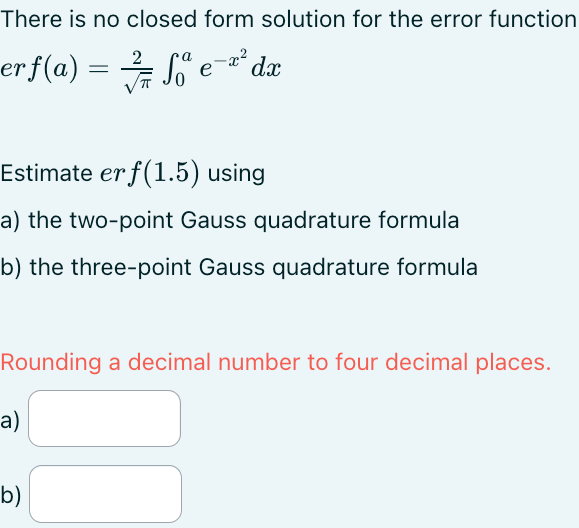

### a

a = 0; b = 1.5; k = 2/sqrt(pi);
f = @(x) exp(-(x.^2))

f = 値をもつ function_handle :
    @(x)exp(-(x.^2))


Itrue = k * integral(f, a, b)

Itrue = 0.9661


a1 = (b+a)/2; a2 = (b-a)/2;
f2 = @(xd) (exp(-(a1 + a2*xd).^2)) * a2;

c0 = 1; c1 = 1;
x0 = -1/sqrt(3); x1 = 1/sqrt(3);
Ig2p = (c0*f2(x0) + c1*f2(x1)) * k

Ig2p = 0.9742

### b

c0 = 5/9; c1 = 8/9; c2 = 5/9;
x0 = -sqrt(3/5); x1 = 0; x2 = sqrt(3/5);
Ig3p = (c0*f2(x0) + c1*f2(x1) + c2*f2(x2)) * k

Ig3p = 0.9655

## Q3 [CORRECT]

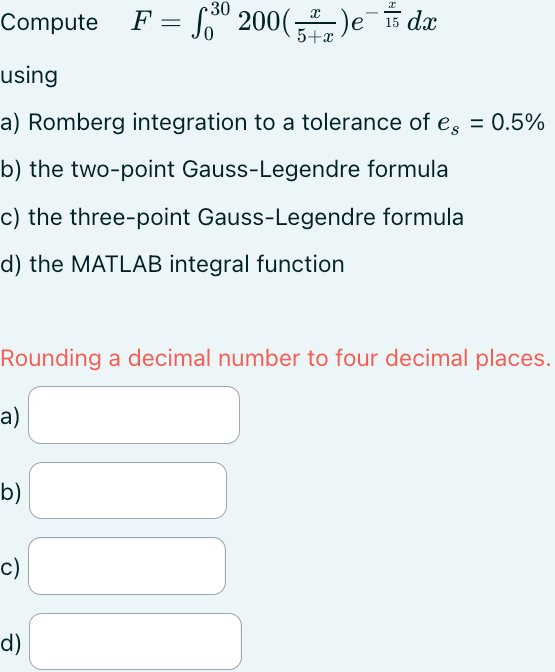

f = @(x) 200 .* (x./(5+x)) .* exp(-x/15);
a = 0; b = 30;

### a

Irb = romberg(f, a, b, 0.5)

Irb = 1.4768e+03

fprintf("%.4f", Irb)

1476.7973

### b

a1 = (b+a)/2; a2 = (b-a)/2;
c0 = 1; c1 = 1;
x0 = -1/sqrt(3); x1 = 1/sqrt(3);
f2 = @(xd) (200 * ((a1 + a2.*xd)/(5+(a1 + a2.*xd))) * exp(-(a1 + a2.*xd)/15)) * a2;
Ig2p = c0*f2(x0) + c1*f2(x1)

Ig2p = 1.6106e+03

fprintf("%.4f", Ig2p)

1610.5723

### c

c0 = 5/9; c1 = 8/9; c2 = 5/9;
x0 = -sqrt(3/5); x1 = 0; x2 = sqrt(3/5);
Ig3p = c0*f2(x0) + c1*f2(x1) + c2*f2(x2)

Ig3p = 1.5103e+03

fprintf("%.4f", Ig3p)

1510.3329

### d

Iint = integral(f, a, b)

Iint = 1.4806e+03

fprintf("%.4f", Iint)

1480.5685

## Q4 [CORRECT]

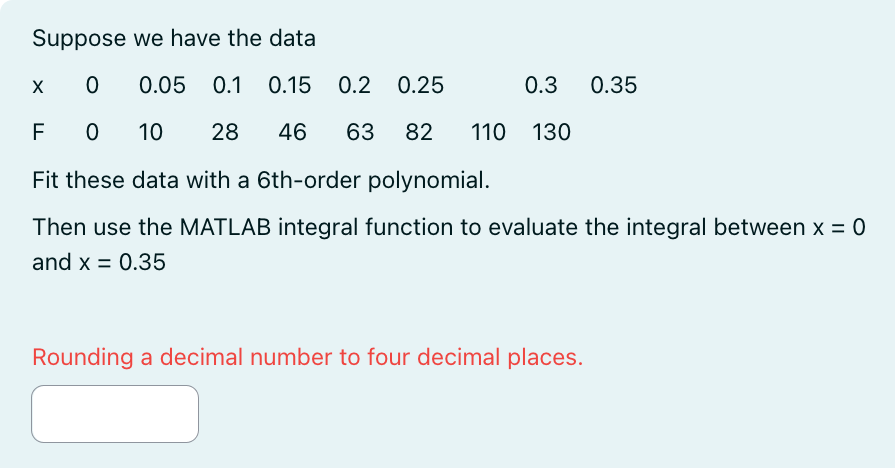

x = [0 0.05 0.1 0.15 0.2 0.25 0.3 0.35];
y = [0 10 28 46 63 82 110 130];
a = 0; b = 0.35;
p6 = polyfit(x, y, 6);
f = @(x) p6(1).*x.^6 + p6(2).*x.^5 + p6(3).*x.^4 + p6(4).*x.^3 + p6(5).*x.^2 + p6(6).*x + p6(7);
Iint = integral(f, a, b)

Iint = 20.2182

## Q5 [CORRECT]

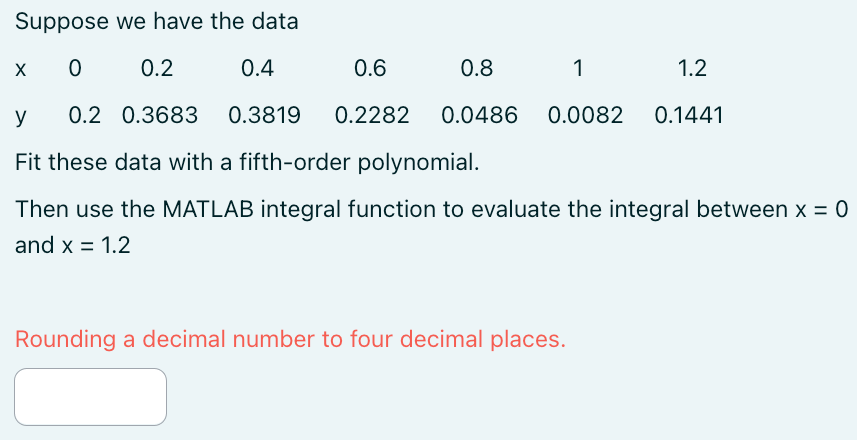

x = [0 0.2 0.4 0.6 0.8 1 1.2];
y = [0.2 0.3683 0.3819 0.2282 0.0486 0.0082 0.1441];
a = 0; b = 1.2;
p5 = polyfit(x, y, 5);
f = @(x) p5(1).*x.^5 + p5(2).*x.^4 + p5(3).*x.^3 + p5(4).*x.^2 + p5(5).*x + p5(6);
Iint = integral(f, a, b)

Iint = 0.2414